1. Determine the perimeter of an object by using 4 connected neighborhoods and 8 connected neighborhoods

img1 = imread('img1.jpg');
perim4 = bwperim(img1,4);
imshowpair(img1,perim4,'montage')
perim8 = bwperim(img1,8);
imshowpair(img1,perim8,'montage')


2. Create a binary image using threshold.

img2 = imread('img2.jpg');
BW = im2bw(img2,0.5);
imshowpair(img2,BW,'montage')

3. Determine the number of objects in the binary image generated in Question 2 using the concept of connectivity

img2 = imread('img2.jpg');
img_gray = rgb2gray(img2);
BW = im2bw(img_gray, 0.5);
BWr = bwareaopen(BW, 30);
[L, num] = bwlabel(BWr);
num

4. Find the Euclidean distance between two points of the image. 

img2 = imread('img2.jpg'); 
img_gray = rgb2gray(img2);
bw = im2bw(img_gray, 0.5);
[D,IDX] = bwdist(bw)

5. Apply the following operations using img1 and img2:

ima1 = rgb2gray(imread('img1.jpg')); 
ima2 = rgb2gray(imread('img2.jpg')); 

imfinfo("img1.jpg");
imfinfo("img2.jpg");

i1 = imresize(ima1,[1024,1024]);
i2 = imresize(ima2,[1024,1024]);

subplot(2,2,1);
addition = imadd(i1, i2);
imshow(addition);
title('Addition');

subplot(2,2,2);
subtract = imsubtract(i1, i2);
imshow(subtract);
title('Subtraction');

subplot(2,2,3);
multiply = immultiply(i1, i2);
imshow(multiply);
title('Multiplication');

subplot(2,2,4);
divide = imdivide(i1, i2);
imshow(divide);
title('Division');

6. Apply the following operations using img1 and img2:

andOperation = and(i1, i2)
subplot(2,2,1);
imshow(andOperation);
title('And');

orOperation = or(i1, i2)
subplot(2,2,2);
imshow(orOperation);
title('Or');

not1Operation = not(i1)
subplot(2,2,3);
imshow(not1Operation);
title('not-img1');

not2Operation = not(i2)
subplot(2,2,4);
imshow(not2Operation);
title('not-img2');


7. Find the digital negative of the image

img3 = rgb2gray(imread('img3.jpg')); 
L = 256;
dneg = (L-1)-img3;

subplot(2,1,1);
imshow(img3);
title('Before');

subplot(2,1,2);
imshow(dneg);
title('After');

8. Apply bit plane slicing on the image

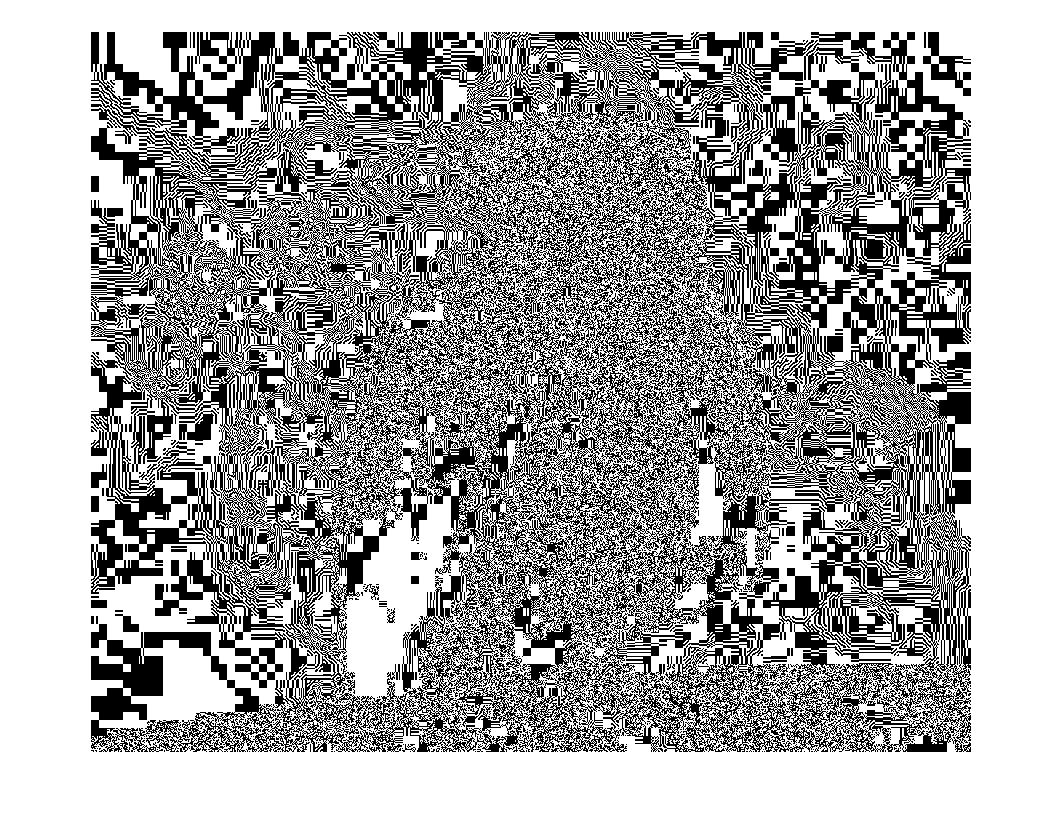

img4 = imread('img4.jpg'); 

img4 = double(img4);
b = bitget(img4,1);
figure, imshow(b)

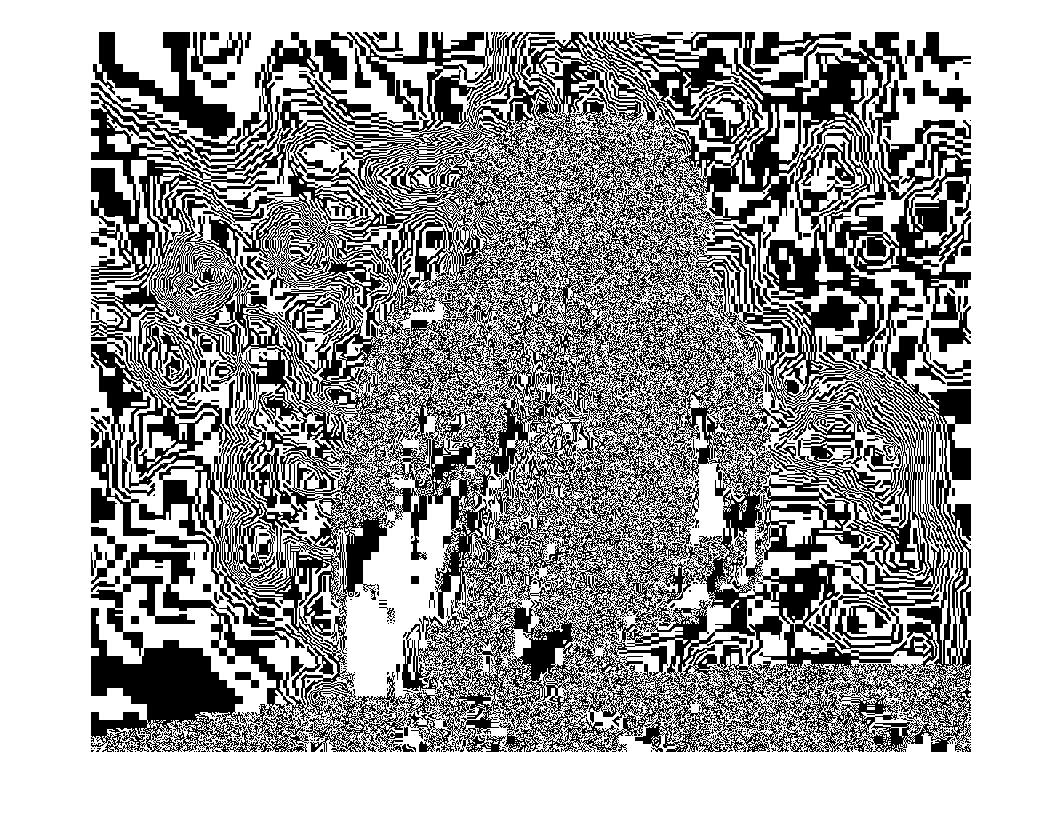

b = bitget(img4,2);
figure, imshow(b)

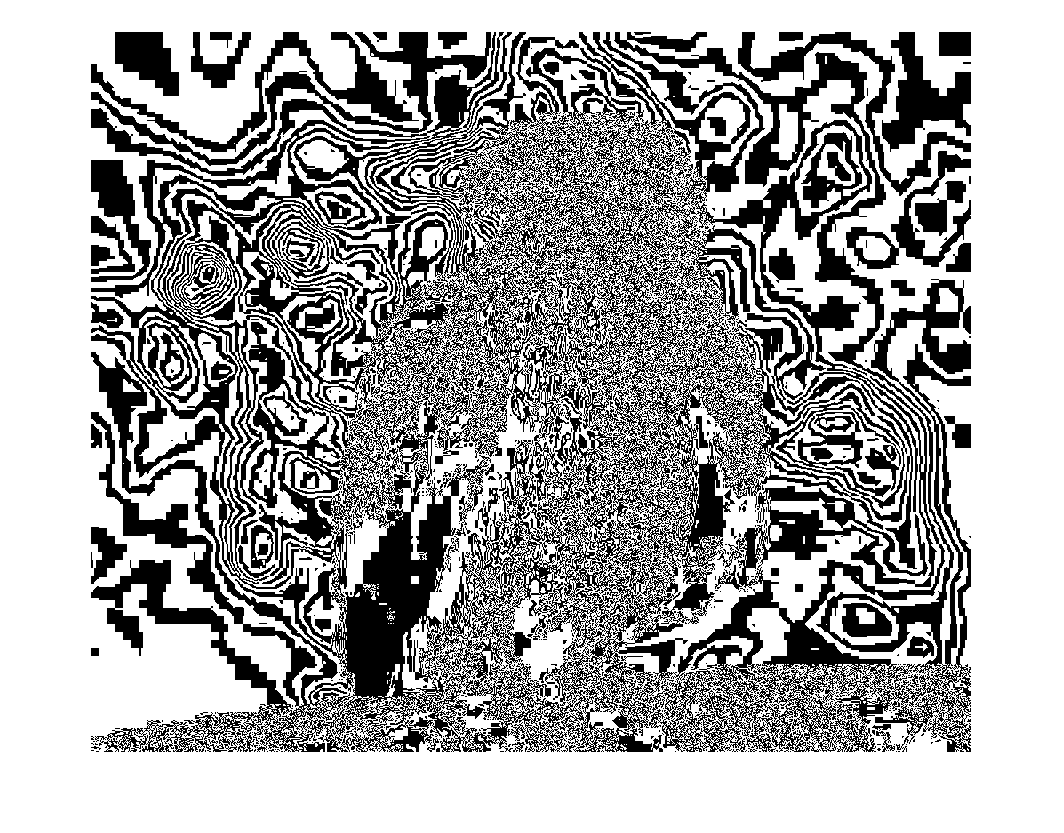

b = bitget(img4,3);
figure, imshow(b)

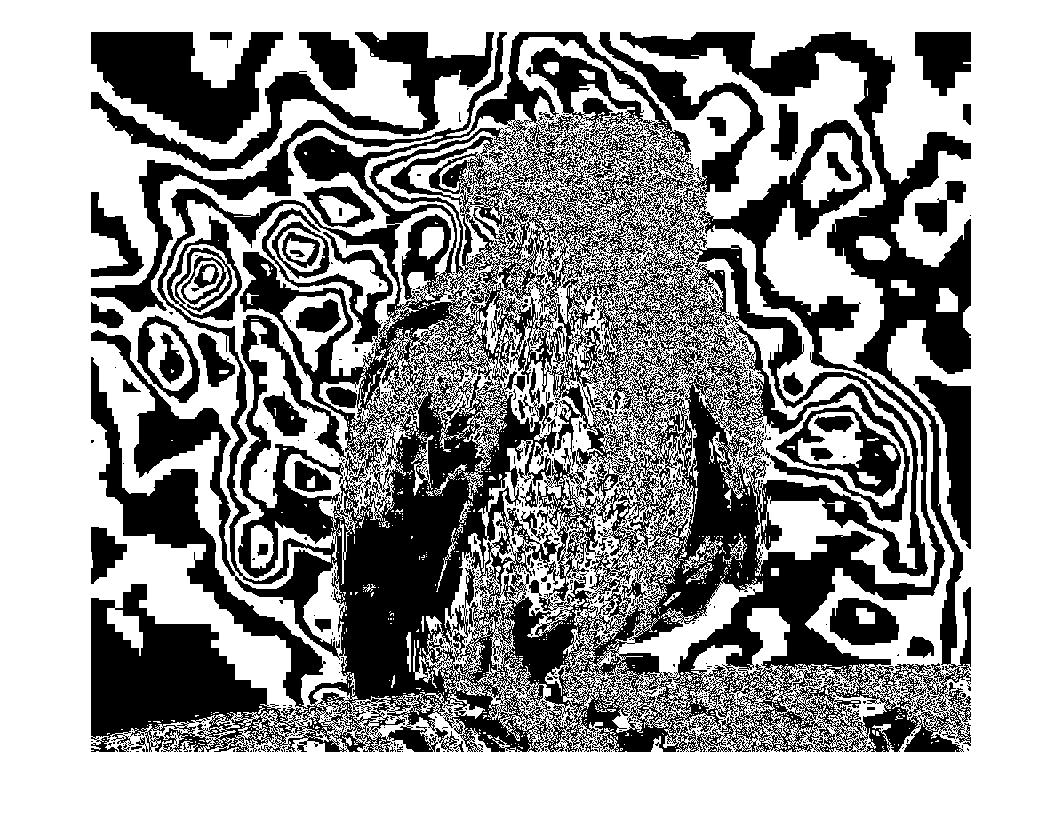

b = bitget(img4,4);
figure, imshow(b)

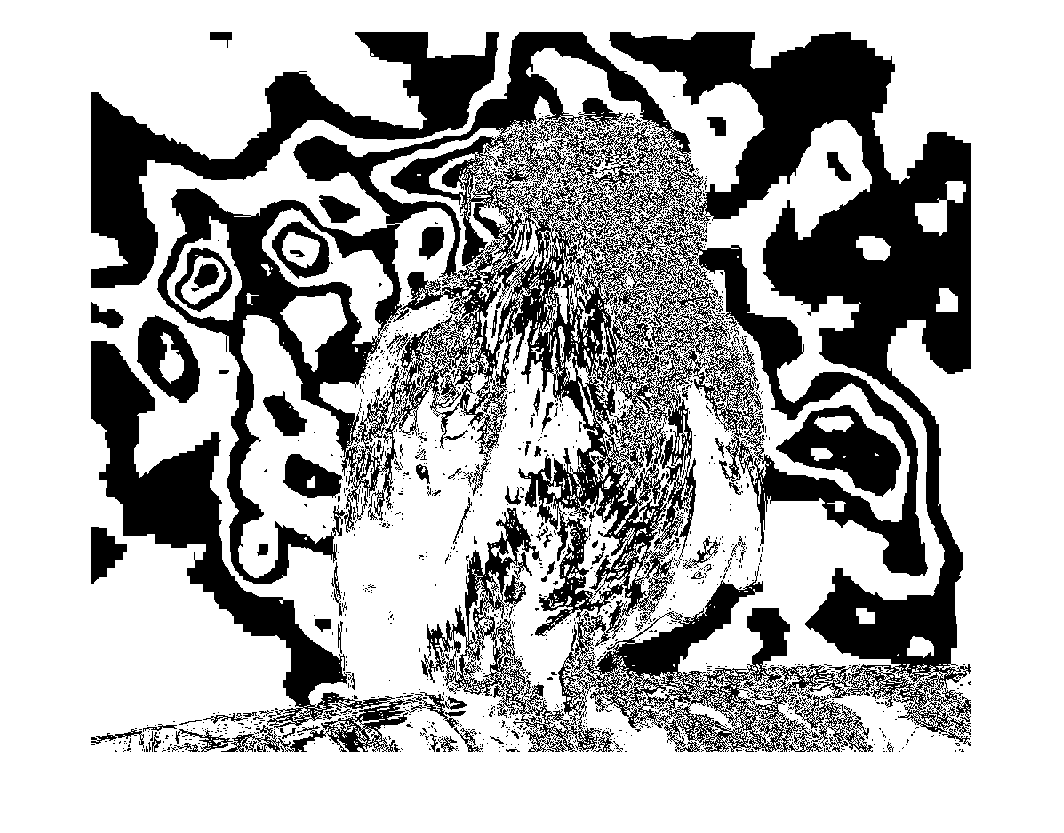

b = bitget(img4,5);
figure, imshow(b)

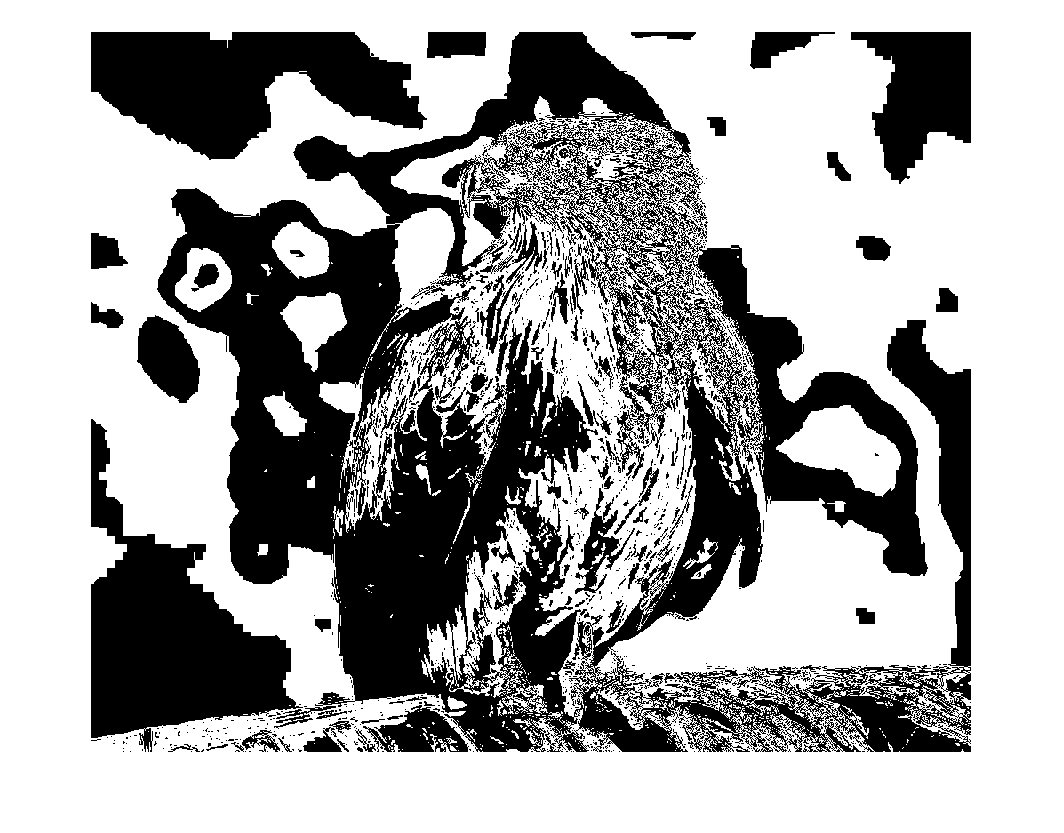

b = bitget(img4,6);
figure, imshow(b)

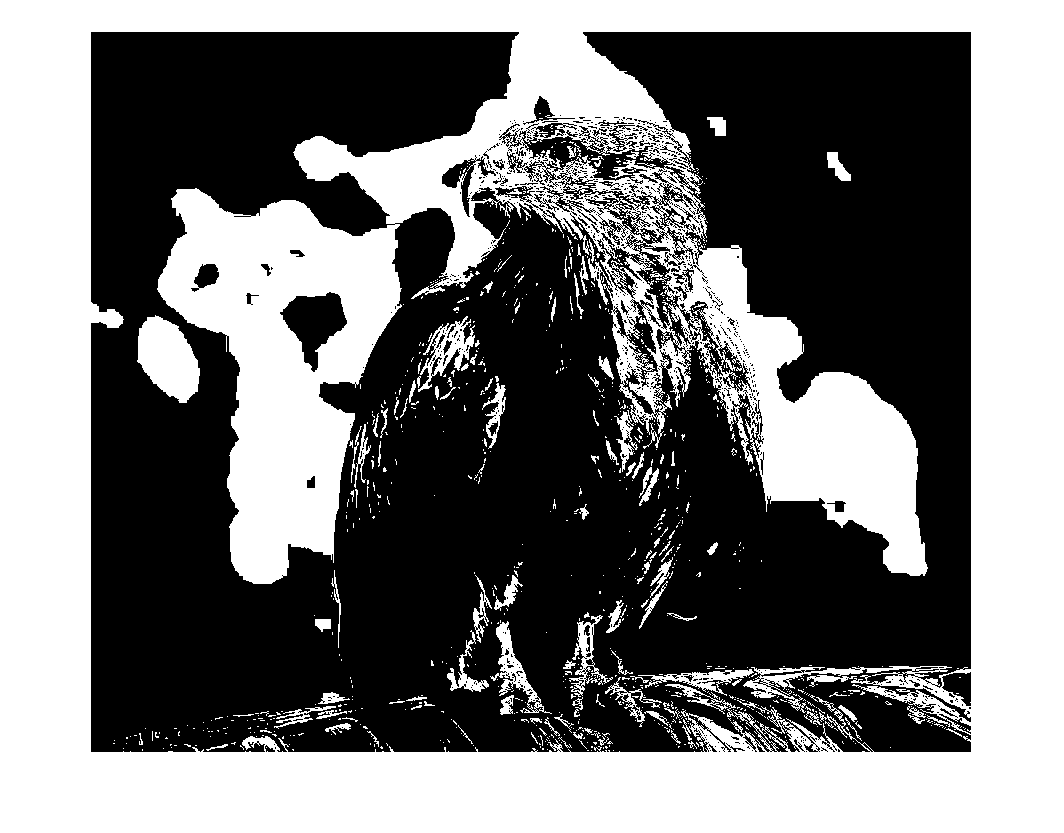

b = bitget(img4,7);
figure, imshow(b)

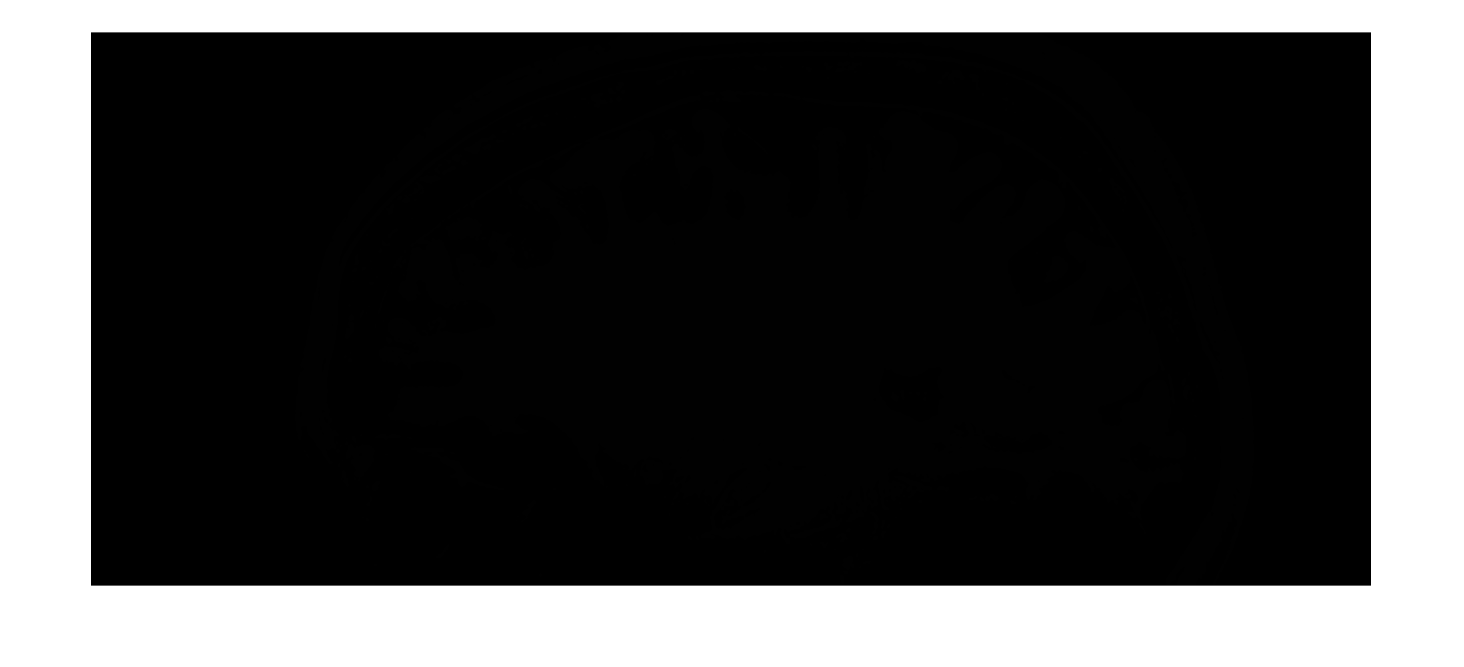

b = bitget(img3,8);
figure, imshow(b)

9. Use contrast stretching on the image.

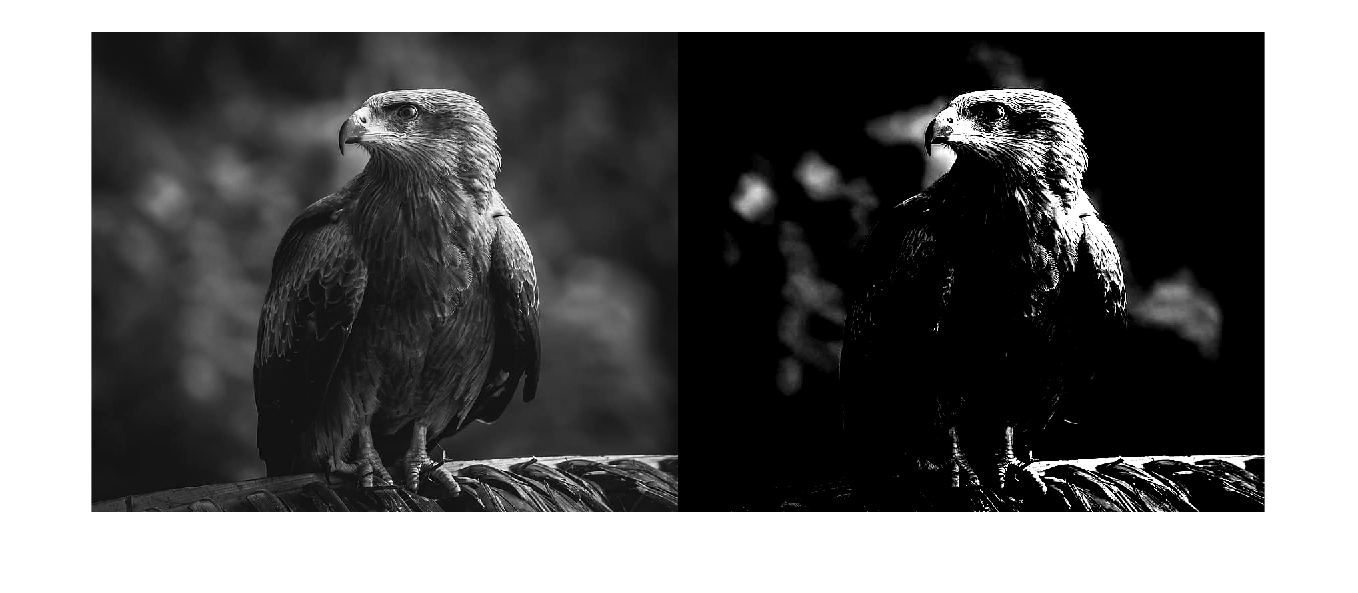

img4 = imread('img4.jpg'); 

ims = imadjust(img4,[0.3, 0.6], [0.0, 1.0]);
imshowpair(img4,ims,'montage')

10. Change the contrast of the image using Logarithmic Transformation and Power-law Transformation.

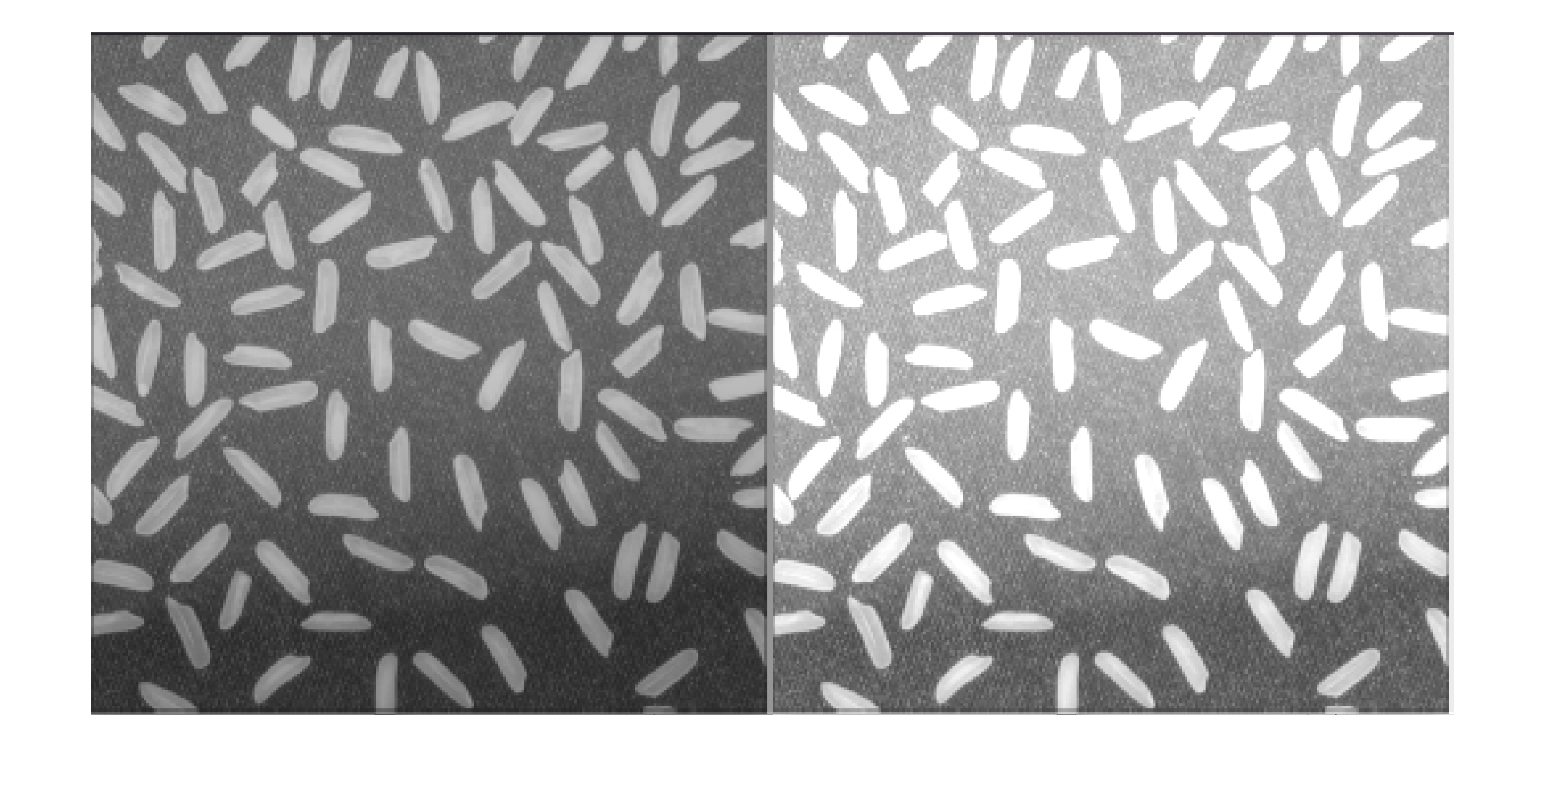

img2 = imread('img2.jpg');
double_v = im2double(img1);

LT = 2*log(1+double_v);
imshowpair(img2,LT,'montage')

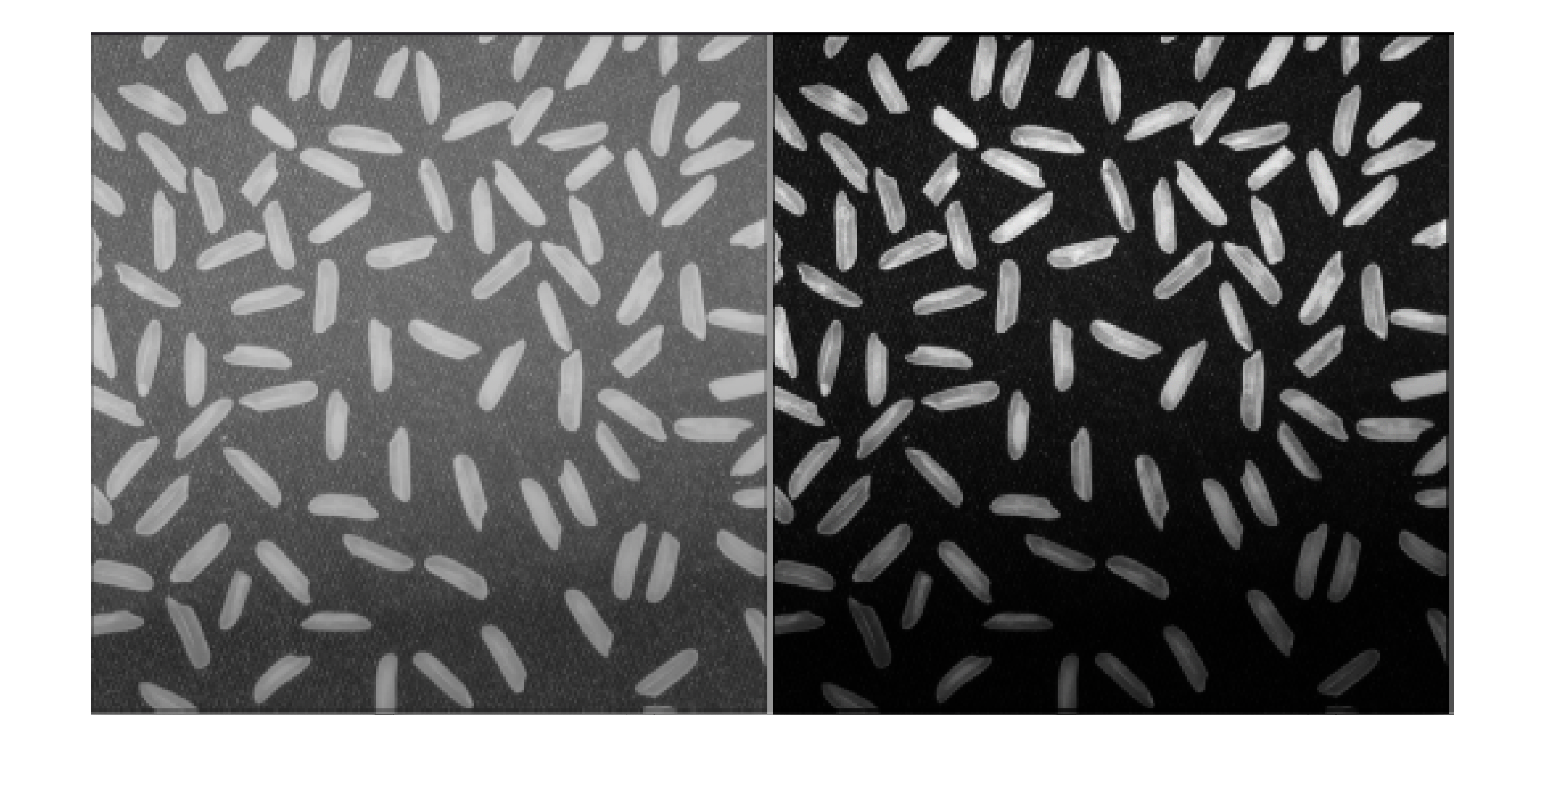


PT =2*(double_v.^3.5);
imshowpair(img2,PT,'montage')